## Vector Functions 

*By Papa Kofi Boahen.*

syms x y z % declare symbolic variables

## Gradient operates on a scalar field(function)

f(x,y,z) = x^2 + 3*y + 2*z;
variables = [x y z];
directional_derivative = gradient(f,variables)

$$directional\_derivative(x, y, z) = \left(\begin{array}{c} 2\,x\\ 3\\ 2 \end{array}\right)$$

## The curl operates on a vector field


vector_field = [x^2+y y^2-z z^2+x];
curl_vector = curl(vector_field, variables)

$$curl\_vector = \left(\begin{array}{c} 1\\ -1\\ -1 \end{array}\right)$$

## gradient cannot be performed on a vector field

% gradient(vector_field,variables)


## The divergence of the curl equals to zero

div = divergence(curl_vector, variables)

$$div = 0$$

## The curl of the gradient of f is also zero

div2 = curl(gradient(f,variables), variables)

$$div2(x, y, z) = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

Sample questions. Compute $(\overrightarrow{A} \times \nabla)\phi$. Use the logic

$\nabla \times A = -A \times \nabla$, but $curl(-A) = \nabla \times -A = A \times \nabla$

A = [2*y*z -x^2*y x*z^2]

$$A = \left(\begin{array}{ccc} 2\,y\,z & -x^{2}\,y & x\,z^{2} \end{array}\right)$$

phi = 2*x^2*y*z^3

$$phi = 2\,x^{2}\,y\,z^{3}$$

result = phi*curl(-A, variables)

$$result = \left(\begin{array}{c} 0\\ -2\,x^{2}\,y\,z^{3}\,\left(2\,y-z^{2}\right)\\ 2\,x^{2}\,y\,z^{3}\,\left(2\,z+2\,x\,y\right) \end{array}\right)$$

## Compute partial derivatives

% using lambda functions
g = @(x,y,z) 2*x^2*y*z^3

g = function_handle with value:
    @(x,y,z)2*x^2*y*z^3


A = [2*y*z;-x^2*y;x*z^2]


$$\frac{\partial g(x,y,z)}{\partial x}  = 2x $$
  

wrt_x = diff(g,x)

$$wrt\_x = 4\,x\,y\,z^{3}$$

wrt_y = diff(g,y)

$$wrt\_y = 2\,x^{2}\,z^{3}$$

wrt_z = diff(g,z)

$$wrt\_z = 6\,x^{2}\,y\,z^{2}$$

sigma = [2*x^2*y*z^3]

$$sigma = 2\,x^{2}\,y\,z^{3}$$

res = gradient(sigma)

$$res = \left(\begin{array}{c} 4\,x\,y\,z^{3}\\ 2\,x^{2}\,z^{3}\\ 6\,x^{2}\,y\,z^{2} \end{array}\right)$$

$$A = \left(\begin{array}{c} 2\,y\,z\\ -x^{2}\,y\\ x\,z^{2} \end{array}\right)$$

answer = cross(A, res)

$$ans = \left(\begin{array}{c} -6\,x^{4}\,y^{2}\,z^{2}-2\,x^{3}\,z^{5}\\ 4\,x^{2}\,y\,z^{5}-12\,x^{2}\,y^{2}\,z^{3}\\ 4\,x^{3}\,y^{2}\,z^{3}+4\,x^{2}\,y\,z^{4} \end{array}\right)$$

## direction cosines

a = [2 1 -1];
b = [1 -1 2];
c = [1 -2 1];
v = a + b - 2*c;

v =      1     4    -1


mag = sym(norm(v))

$$mag = 3\,\sqrt{2}$$

% use the user-defined function direction
[alpha, beta, gamma] = direction(v, mag)

$$alpha = \frac{\sqrt{2}}{6}$$

$$beta = \frac{2\,\sqrt{2}}{3}$$

$$gamma = -\frac{\sqrt{2}}{6}$$

## Work done by constant forces

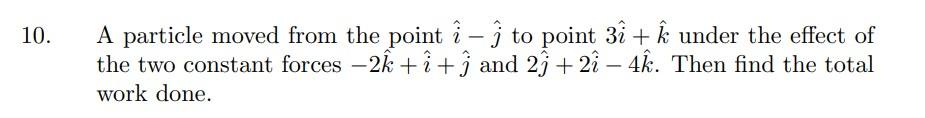

% Question 9
p = [0 1 -2]; % starting point
q = [5 1 2];% ending poing
f1 = [1 2 3]; % force 1
f2 = [3 1 1]; % force 2

% displacement
p_q = q - p;
% resultant force
resultant1 = f1 + f2;
% Work done
work1 = dot(resultant1, p_q)

work1 = 36


% Question 10
p1 = [ 1 -1 0];
q2 = [3 0 1];
f3 = [1 1 -2];
f4 = [2 2 -4];
% displacement
p_q2 = q2 - p1;
% resultant force
resultant2 = f3 + f4;
% Work done
work2 = dot(resultant2, p_q2)

work2 = 3